Clear all the paramters from the workspace and also celar the command window.

clear all
clc

Define initial conditions (they are the same for both methods).

q0_0 = [0 0 0]';
q0_1 = [pi/2 pi/2 pi/2]';

Desired position of the end effector

x_de = [2 1 0]';

syms x y z

Define symbolyc direct kinematics

K = [cos(x)+cos(x+y)+cos(x+y+z),sin(x)+sin(x+y)+sin(x+y+z),x+y+z]'

$$K = \left(\begin{array}{c} \cos\left(\bar{x}\right)+\cos\left(\bar{x}+\bar{y}+\bar{z}\right)+\cos\left(\bar{x}+\bar{y}\right)\\ \sin\left(\bar{x}\right)+\sin\left(\bar{x}+\bar{y}+\bar{z}\right)+\sin\left(\bar{x}+\bar{y}\right)\\ \bar{x}+\bar{y}+\bar{z} \end{array}\right)$$

Define symbolic jacobian

J = jacobian([cos(x)+cos(x+y)+cos(x+y+z),sin(x)+sin(x+y)+sin(x+y+z),x+y+z],[x,y,z])

$$J = \left(\begin{array}{ccc} -\sin\left(x+y+z\right)-\sin\left(x+y\right)-\sin\left(x\right) & -\sin\left(x+y+z\right)-\sin\left(x+y\right) & -\sin\left(x+y+z\right)\\ \cos\left(x+y+z\right)+\cos\left(x+y\right)+\cos\left(x\right) & \cos\left(x+y+z\right)+\cos\left(x+y\right) & \cos\left(x+y+z\right)\\ 1 & 1 & 1 \end{array}\right)$$

# **GRADIENT METHOD**

Define the step sizes

alpha_1 = 1/2;
alpha_2 = 1/10;

# Step-Size α=1/2

max_iter = 500;
err_threshold = 1e-5;

Running tests

[q1, num_iter1, err1] = gradient_method(J, K, q0_0, x_de, alpha_1, max_iter, err_threshold);
[q2, num_iter2, err2] = gradient_method(J, K, q0_1, x_de, alpha_1, max_iter, err_threshold);

## RESULTS

Solution starting from [0 0 0] with α = 1/2 in degrees

disp(q1(:,num_iter1)*180/pi);

  -56.1863
 -243.9567
  107.2643



Evaluation of the direct kinematics at the solution obtained

disp(double(subs(K,{x,y,z},q1(:,num_iter1)')))

    0.0838
    0.2568
   -3.3664



Number of iteration required

num_iter1

num_iter1 = 500

Solution starting from [π/2 π/2 π/2] with α= 1/2 in degrees

disp(q2(:,num_iter2)*180/pi);

  -42.4657
   95.8928
 -223.3776



Evaluation of the direct kinematics at the solution obtained

disp(double(subs(K,{x,y,z},q2(:,num_iter2)')))

    0.3489
   -0.0465
   -2.9662



Number of iteration required

num_iter2

num_iter2 = 500

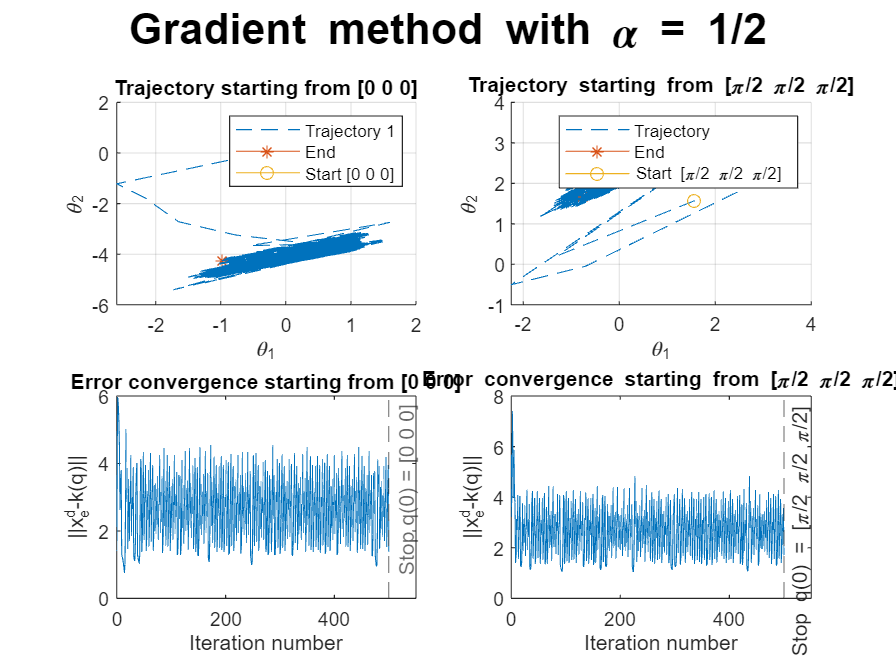

figure()
sgt = sgtitle('Gradient method with \alpha = 1/2');
sgt.FontSize = 20;
sgt.FontWeight = 'bold';
subplot(2,2,1)
hold on
plot3(q1(1,:),q1(2,:),q1(3,:),'DisplayName','Trajectory 1 ','LineStyle','--')
plot3(q1(1,num_iter1),q1(2,num_iter1),q1(3,num_iter1),'Marker','*','DisplayName','End')
plot3(q1(1,1),q1(2,1),q1(3,1),'Marker','o','DisplayName','Start [0 0 0]')
title('Trajectory starting from [0 0 0]')
xlabel('\theta_1')
ylabel('\theta_2')
zlabel('\theta_3')
legend()
grid on

subplot(2,2,2)
hold on
plot3(q2(1,:),q2(2,:),q2(3,:),'DisplayName','Trajectory','LineStyle','--')
plot3(q2(1,num_iter2),q2(2,num_iter2),q2(3,num_iter2),'Marker','*','DisplayName','End')
plot3(q2(1,1),q2(2,1),q2(3,1),'Marker','o','DisplayName','Start [\pi/2 \pi/2 \pi/2]')
title('Trajectory starting from [\pi/2 \pi/2 \pi/2]')
xlabel('\theta_1')
ylabel('\theta_2')
zlabel('\theta_3')
legend()
grid on

subplot(2,2,3)
plot(0:num_iter1, err1(1,1:(num_iter1+1)))
xlabel('Iteration number')
ylabel('﻿||x_{e}^{d}-k(q)||')
xline(num_iter1,'--','Stop q(0) = [0 0 0]','LabelHorizontalAlignment','right');
xlim([0 num_iter1+50]);
title('Error convergence starting from [0 0 0]')
subplot(2,2,4)
plot(0:num_iter2, err2(1,1:(num_iter2+1)))
xline(num_iter2,'--','Stop q(0) = [\pi/2 \pi/2 \pi/2]','LabelHorizontalAlignment','right');
xlim([0 num_iter2+50]);
xlabel('Iteration number')
ylabel('﻿||x_{e}^{d}-k(q)||')
title('Error convergence starting from [\pi/2 \pi/2 \pi/2]')

# Step-Size α=1/10

% clear variables to avoid errors with variable dimensions
clear q1 q2 err1  err2
max_iter =1000;

Running tests

err_threshold = 1e-4;

[q1, num_iter1, err1] = gradient_method(J, K, q0_0, x_de, alpha_2, max_iter, err_threshold);

err_threshold = 1e-5;

[q2, num_iter2, err2] = gradient_method(J, K, q0_0, x_de, alpha_2, max_iter, err_threshold);
[q3, num_iter3, err3] = gradient_method(J, K, q0_1, x_de, alpha_2, max_iter, err_threshold);

Solution starting from [0 0 0] with α = 1/2 in degrees err_threshold

disp(q1(:,num_iter1)*180/pi);

   48.1550
    4.8945
  -69.7472



Evaluation of the direct kinematics at the solution obtained

disp(double(subs(K,{x,y,z},q1(:,num_iter1)')))

    2.2261
    1.2568
   -0.2914



Number of iteration required

num_iter1

num_iter1 = 83

disp(q2(:,num_iter2)*180/pi);

    0.0366
   89.9571
  -90.0134



Evaluation of the direct kinematics at the solution obtained

disp(double(subs(K,{x,y,z},q2(:,num_iter2)')))

    2.0001
    1.0003
   -0.0003



Number of iteration required

num_iter2

num_iter2 = 648

Solution starting from [π/2 π/2 π/2] with α= 1/2 in degrees

disp(q3(:,num_iter3)*180/pi);

    0.0366
   89.9570
  -90.0133



Evaluation of the direct kinematics at the solution obtained

disp(double(subs(K,{x,y,z},q3(:,num_iter3)')))

    2.0001
    1.0003
   -0.0003



Number of iteration required

num_iter3

num_iter3 = 370

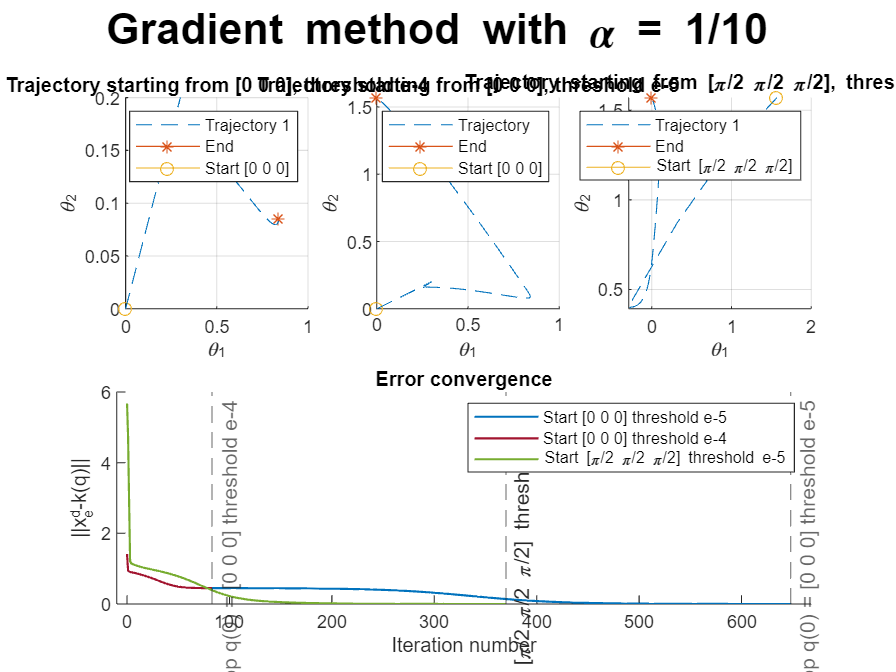


figure()
sgt = sgtitle('Gradient method with \alpha = 1/10 ');
sgt.FontSize = 20;
sgt.FontWeight = 'bold';

% plotting q1 trajectory
subplot(2,3,1)
hold on
plot3(q1(1,:),q1(2,:),q1(3,:),'DisplayName','Trajectory 1 ','LineStyle','--')
plot3(q1(1,num_iter1),q1(2,num_iter1),q1(3,num_iter1),'Marker','*','DisplayName','End')
plot3(q1(1,1),q1(2,1),q1(3,1),'Marker','o','DisplayName','Start [0 0 0]')
title('Trajectory starting from [0 0 0], threshold e-4')
xlabel('\theta_1')
ylabel('\theta_2')
zlabel('\theta_3')
legend()
grid on

% plotting q2 trajectory
subplot(2,3,2)
hold on
plot3(q2(1,:),q2(2,:),q2(3,:),'DisplayName','Trajectory','LineStyle','--')
plot3(q2(1,num_iter2),q2(2,num_iter2),q2(3,num_iter2),'Marker','*','DisplayName','End')
plot3(q2(1,1),q2(2,1),q2(3,1),'Marker','o','DisplayName','Start [0 0 0]')
title('Trajectory starting from [0 0 0], threshold e-5')
xlabel('\theta_1')
ylabel('\theta_2')
zlabel('\theta_3')
legend()
grid on

subplot(2,3,3)
hold on
plot3(q3(1,:),q3(2,:),q3(3,:),'DisplayName','Trajectory 1 ','LineStyle','--')
plot3(q3(1,num_iter3),q3(2,num_iter3),q3(3,num_iter3),'Marker','*','DisplayName','End')
plot3(q3(1,1),q3(2,1),q3(3,1),'Marker','o','DisplayName','Start [\pi/2 \pi/2 \pi/2]')
title('Trajectory starting from [\pi/2 \pi/2 \pi/2], threshold e-5')
xlabel('\theta_1')
ylabel('\theta_2')
zlabel('\theta_3')
legend()
grid on

% plotting errors
subplot(2,3,[4,5,6])
hold on
plot(0:num_iter2, err2(1,1:(num_iter2+1)), 'LineWidth',1)
plot(0:num_iter1, err1(1,1:(num_iter1+1)) ,'Color', '#A2142F', 'LineWidth',1)
plot(0:num_iter3, err3(1,1:(num_iter3+1)), 'Color', '#77AC30', 'LineWidth',1)
xline(num_iter1,'--','Stop q(0) = [0 0 0] threshold e-4','LabelHorizontalAlignment','right');
xline(num_iter2,'--','Stop q(0) = [0 0 0] threshold e-5','LabelHorizontalAlignment','right');
xline(num_iter3,'--','Stop q(0) = [\pi/2 \pi/2 \pi/2] threshold e-5','LabelHorizontalAlignment','right');

xlabel('Iteration number')
ylabel('﻿||x_{e}^{d}-k(q)||')
title('Error convergence')
xlim([-10 num_iter2+20]);
legend('Start [0 0 0] threshold e-5', 'Start [0 0 0] threshold e-4', 'Start [\pi/2 \pi/2 \pi/2] threshold e-5')

# **NEWTON'S METHOD**

% clear variables to avoid errors with variable dimensions
clear q1 q2 err1  err2
max_iter = 20;
err_threshold = 1e-5;

Running tests

[q1, num_iter1, err1] = newton_method(J, K, q0_0, x_de, max_iter, err_threshold);
[q2, num_iter2, err2] = newton_method(J, K, q0_1, x_de, max_iter, err_threshold);

## RESULTS

Solution starting from [0 0 0] in degrees

disp(q1(:,num_iter1)*180/pi);

  450.0000
 -810.0000
  360.0000



Solution starting from [0 0 0] in degrees inside [0 360]

disp(mod(q1(:,num_iter1),2*pi)*180/pi);

   90.0000
  270.0000
    0.0000



Evaluation of the direct kinematics at the solution obtained

disp(double(subs(K,{x,y,z},q1(:,num_iter1)')))

    2.0000
    1.0000
         0



Number of iteration required

num_iter1

num_iter1 = 7

Solution starting from [π/2 π/2 π/2] in degrees

disp(q2(:,num_iter2)*180/pi);

 -360.0000
  450.0000
  -90.0000



Solution starting from [0 0 0] in degrees inside [0 360]

disp(mod(q2(:,num_iter2),2*pi)*180/pi);

    0.0000
   90.0000
  270.0000



Evaluation of the direct kinematics at the solution obtained

disp(double(subs(K,{x,y,z},q2(:,num_iter2)')))

    2.0000
    1.0000
   -0.0000



Number of iteration required

num_iter2

num_iter2 = 6

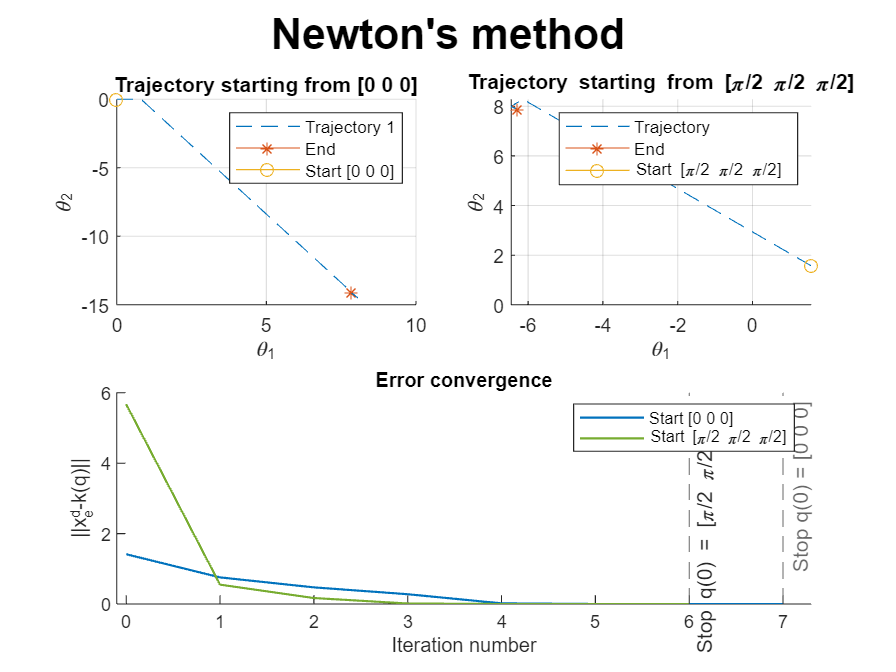


figure()
sgt = sgtitle('Newton''s method');
sgt.FontSize = 20;
sgt.FontWeight = 'bold';
subplot(2,2,1)
hold on
plot3(q1(1,:),q1(2,:),q1(3,:),'DisplayName','Trajectory 1 ','LineStyle','--')
plot3(q1(1,num_iter1),q1(2,num_iter1),q1(3,num_iter1),'Marker','*','DisplayName','End')
plot3(q1(1,1),q1(2,1),q1(3,1),'Marker','o','DisplayName','Start [0 0 0]')
title('Trajectory starting from [0 0 0]')
xlabel('\theta_1')
ylabel('\theta_2')
zlabel('\theta_3')
legend()
grid on

subplot(2,2,2)
hold on
plot3(q2(1,:),q2(2,:),q2(3,:),'DisplayName','Trajectory','LineStyle','--')
plot3(q2(1,num_iter2),q2(2,num_iter2),q2(3,num_iter2),'Marker','*','DisplayName','End')
plot3(q2(1,1),q2(2,1),q2(3,1),'Marker','o','DisplayName','Start [\pi/2 \pi/2 \pi/2]')
title('Trajectory starting from [\pi/2 \pi/2 \pi/2]')
xlabel('\theta_1')
ylabel('\theta_2')
zlabel('\theta_3')
legend()
grid on

subplot(2,2,[3,4])
hold on
plot(0:num_iter1, err1(1,1:(num_iter1+1)), 'LineWidth',1)
plot(0:num_iter2, err2(1,1:(num_iter2+1)), 'LineWidth',1, 'Color', '#77AC30')
xline(num_iter1,'--','Stop q(0) = [0 0 0]','LabelHorizontalAlignment','right');
xline(num_iter2,'--','Stop q(0) = [\pi/2 \pi/2 \pi/2]','LabelHorizontalAlignment','right');
legend('Start [0 0 0]', 'Start [\pi/2 \pi/2 \pi/2]')
xlim([-0.1 num_iter1+0.3]);
title('Error convergence')
xlabel('Iteration number')
ylabel('﻿||x_{e}^{d}-k(q)||')

# ***GRADIENT METHOD FUNCTION***

function [q, n_iter, err] = gradient_method(Jacobian, k, q_0, x_des, step_size, max_iter, err_threshold)
    % Initializing necessary variables and matrices
    syms x y z
    q_temp = zeros(3,max_iter);
    err_temp = zeros(1, max_iter+1);
    n_iter = 0;
    % Finding the error at iteration 0 
    q_temp(: , 1) = q_0;    
    k_temp = subs(k,{x,y,z},q_temp(:,1)');
    err_temp(1) = norm(x_des-k_temp);
    
    j = 2;
    while (n_iter < max_iter)
        n_iter = j-1;
        % Calculating jacobian at previus iteration's solution
        J_temp = subs(Jacobian,{x,y,z},q_temp(:,j-1)');
        % Solution's updating formula
        q_temp(:,j) = q_temp(:,j-1) + step_size*(J_temp)'*(x_des-k_temp);        
        % Calculating K(q) after the gradient step
        k_temp = subs(k,{x,y,z},q_temp(:,j)');
        % Calculating error at the current iteration
        err_temp(j) = norm(x_des-k_temp);
        % Implementing early stopping strategy
        if abs(err_temp(j)-err_temp(j-1)) < err_threshold
            break  
        end
        j = j+1;
    end
    % Considering as output only nonzero elements
    q = q_temp(:,1:n_iter+1);
    err = err_temp(1:n_iter+1);
end

# ***NEWTON'S METHOD FUNCTION***

function [q, n_iter, err] = newton_method(Jacobian, k, q_0, x_des, max_iter, err_threshold)
    % Initializing necessary variables and matrices    
    syms x y z
    q_temp = zeros(3,max_iter);
    err_temp = zeros(1, max_iter);
    n_iter = 0;
    % Finding the error at iteration 0 
    q_temp(: , 1) = q_0;    
    k_temp = subs(k,{x,y,z},q_temp(:,1)');
    err_temp(1) = norm(x_des-k_temp);

    j = 2;
    while (n_iter < max_iter)
        n_iter = j-1;
        % Calculating jacobian at previus iteration's solution
        J_temp = subs(Jacobian,{x,y,z},q_temp(:,j-1)');       
        % Calculating pseudo-inverse
        J_inv=pinv(J_temp);
        % Solution's updating formula
        q_temp(:,j) = q_temp(:,j-1) + J_inv*(x_des-k_temp);
        % Calculating K(q) after the Newton's step
        k_temp = subs(k,{x,y,z},q_temp(:,j)');
        % Calculating error at the current iteration
        err_temp(j) = norm(x_des-k_temp);
        % Implementing early stopping strategy
        if abs(err_temp(j)-err_temp(j-1)) < err_threshold
            break  
        end
        j = j+1;
    end
    % Considering as output only nonzero elements
    q = q_temp(:,1:n_iter+1); 
    err = err_temp(1:n_iter+1);
end